# Wafers Analysis

A factory produces wafers on which eletrical circuits will be printed.

The process manager asks to verify whether the production process complies with the prescribed proportions.

## Load data

% table of prescribed proportions
T = readtable('wafer.txt')

T = 10×3 table
    Thickness    Length    Width
    _________    ______    _____

        7          4         3  
        4          1         8  
        6          3         5  
        8          6         1  
        8          5         7  
        7          2         9  
        5          3         3  
        9          5         8  
        7          4         5  
        8          2         2  


**Properties of table**

n = height(T)

n = 10

rowNames = "w" + (1:n)

rowNames = 1×10 string array
    "w1"    "w2"    "w3"    "w4"    "w5"    "w6"    "w7"    "w8"    "w9"    "w10"


T.Properties.RowNames = rowNames

T = 10×3 table
           Thickness    Length    Width
           _________    ______    _____

    w1         7          4         3  
    w2         4          1         8  
    w3         6          3         5  
    w4         8          6         1  
    w5         8          5         7  
    w6         7          2         9  
    w7         5          3         3  
    w8         9          5         8  
    w9         7          4         5  
    w10        8          2         2  


columnNames = T.Properties.VariableNames

columnNames = 1×3 cell array
    {'Thickness'}    {'Length'}    {'Width'}


## Plot Parallel Coordinates

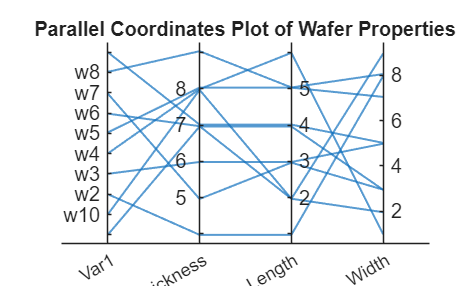

Tt = addvars(T, rowNames', 'Before', 1);
parallelplot(Tt)
title('Parallel Coordinates Plot of Wafer Properties')

**Description:** There are two wafers with same length and thickness but different widths.

- Construct the scatterplot matrix with univariate boxplots on the main diagonal and a background color for each scatter which is proportional to the correlation.

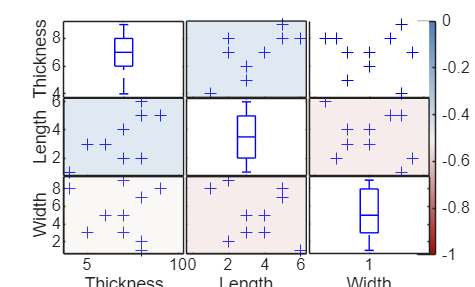

ans =   3×3 graphics array:

    Graphics    Line        Line    
    Line        Graphics    Line    
    Line        Line        Graphics


spmplot(T, 'colorBackground', true, 'dispopt', 'box')